clc
clear all


Elapsed time is 0.111187 seconds.


% Connect to raspi
    robotPi = raspi('192.168.34.159', 'pi', 'raspberry');

% Create connection to the V2 Pi Camera
     robotCam = cameraboard(robotPi, 'Resolution', '1280x720');   


robotCam.ExposureMode = 'sports';
robotCam.AWBMode = 'fluorescent';

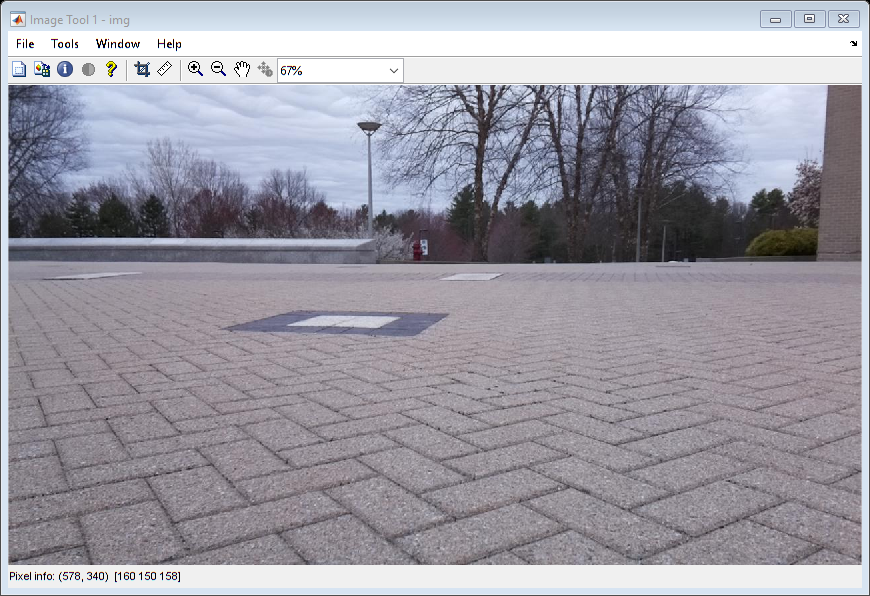


% Acquire a frame
img = snapshotCustom(robotCam);

% Display the frame in the imaqtool window
imtool(img);


clc
imaqreset

a = 720×1280×3 uint8 array
a(:,:,1) =

    54    38    43    50    44    48    52    38    44    47    45    41    44    50    49    44    50    58    61    53    59    86    89    63    80    86    92    91    86    81    81    83    86    88    88    82    69    57    55    59    56    55    54    54    54    51    48    44    51    52    53    50    46    46    49    53    56    55    54    55    56    55    52    49    50    52    53    51    48    45    43    42    45    48    50    50    47    44    42    42    44    41    37    36    38    43    50    54    50    46    42    40    40    40    40    37    38    35    32    32    33    33    32    31    29    30    32    32    32    33    35    37    38    34    38    36    28    48    91   120   111   107   108   110   109   104   102   103   103   117   124   112    90    72    61    55    57    56    55    56    57    56    53    50    52    51    50    50    49    49    49    50    52    51    48    40    31    25    24    23 

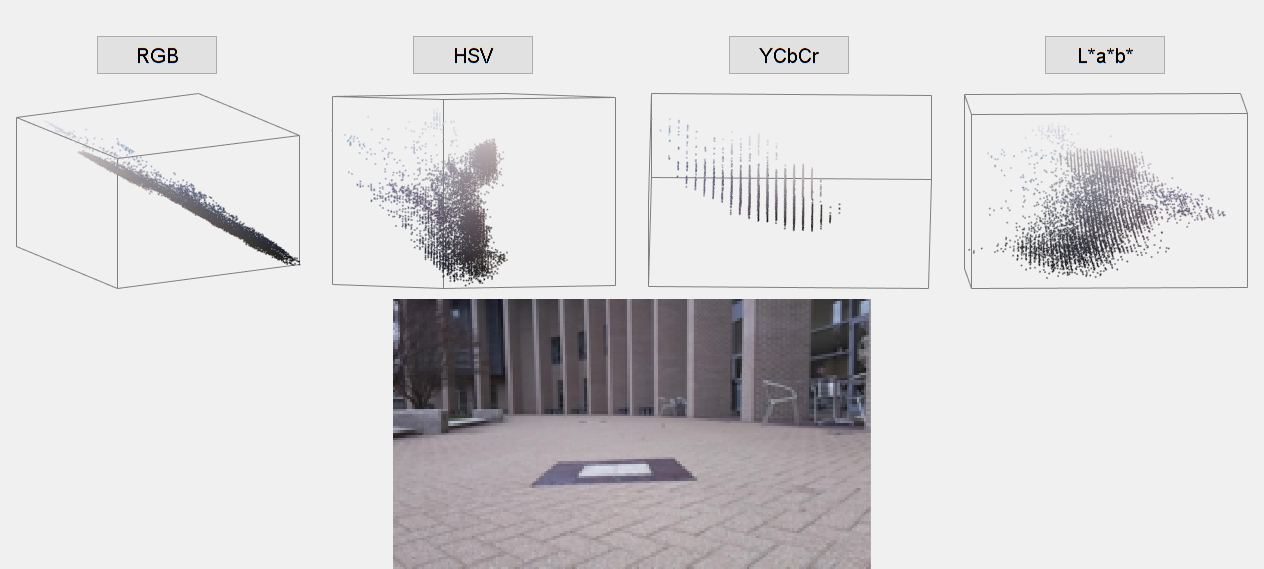


%create a free floating figure for images
% picamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
% figure(picamWindow) % got to camWindow for imshow
% % imshow(img,'Border','tight')
% % Save file
% filename = input('filename:','s');
% saveas(gcf, filename)


function [] = MakeMask(pi,picam)
img = snapshotCustom(picam);
colorThresholder(img)
end